f = @(x) abs(exp(x)-x.^2)+x

f = function_handle with value:
    @(x)abs(exp(x)-x.^2)+x


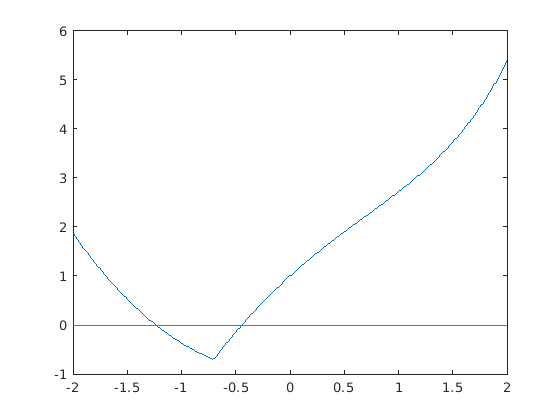

x=-2:0.01:2;
plot(x,f(x),x,zeros(1,length(x)))
hold on

disp("ROOT 1")

ROOT 1


[root,num] = secant_method(f,-2,-1,10^(-5))

root =   -1.235346233695106


num =      5


plot(root,f(root),"r*")
[root,num] = regula_falsi_method(f,-2,-1,10^(-5))

root =   -1.235343659390901


num =      9


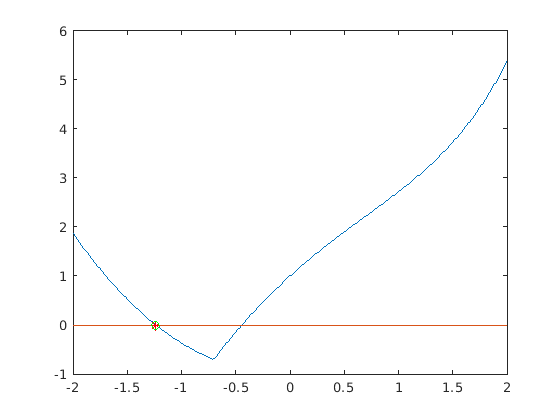

plot(root,f(root),"go")

disp("ROOT 2")

ROOT 2


[root,num] = secant_method(f,-1,2,10^(-5))

root =   -0.444130228823849


num =      7


plot(root,f(root),"r*")
[root,num] = secant_method(f,2,-1,10^(-5))

root =   -1.235346232360305


num =      6


[root,num] = regula_falsi_method(f,-1,2,10^(-5))

root =   -0.444130082926719


num =      6


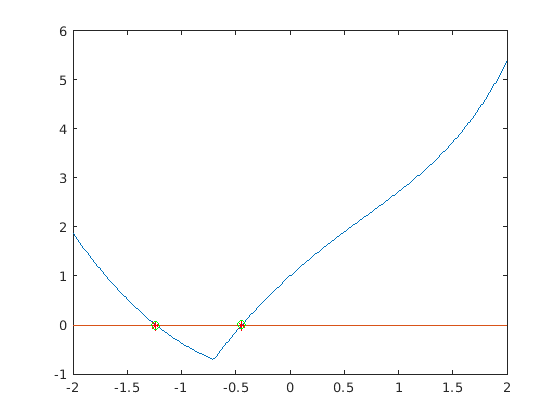

plot(root,f(root),"go")
hold off

function [x2,num] = secant_method(f,x0,x1,error)
%Secant method

f0=f(x0);f1=f(x1);
num=0;
format long
while abs(x0-x1)>error
    x2=x1-f1*(x1-x0)/(f1-f0); 
    f2=f(x2);
    x0=x1;x1=x2;f0=f1;f1=f2;
    num=num+1; 
end
end

function [x2,num] = regula_falsi_method(f,x0,x1,error)
%Secant method
root_found=false;
f0=f(x0);f1=f(x1);
x2=x1-f1*(x1-x0)/(f1-f0);
f2=f(x2);
num=1;
format long
while abs(x2-x1)>error && not(root_found)
    if (f2*f0<0) 
        x1=x2;f1=f2;
    elseif (f2*f1<0)
        x0=x1;x1=x2;f0=f1;f1=f2;
    else
        root_found=true;
    end
    x2=x1-f1*(x1-x0)/(f1-f0);
    f2=f(x2);
    num=num+1; 
end
end